# Convection and conservation of mass equations

## Initial conditions

% Speed function u(t, x)
a = -.2; b = -.05;
% a = 2; b = 1;

u = @(t, x) a*x + b;
dudt = @(t, x) zeros(size(x));
dudx = @(t, x) a*ones(size(x));

% u = @(t, x) a*x/200 - .5*t.*x;
% dudt = @(t, x) -.5*x;
% dudx = @(t, x) a/200 - .5*t;

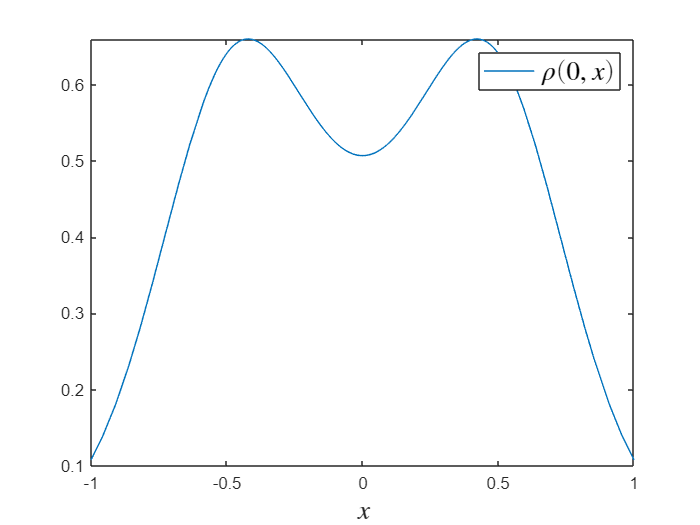

% Integration time
T = 1;
t = linspace(0, T, 11);

% Segment of interest
x0 = linspace(-1, 1, 25);

% Initial density distribution
rho_fun = @(x) .5*normpdf(x, 0, .5) + ...
    .25*normpdf(x, -.5, .25) + ...
    .25*normpdf(x, .5, .25);
rho_0 = rho_fun(x0);


figure(1);
fplot(rho_fun, [min(x0), max(x0)]);
xlabel('$x$', Interpreter = 'latex', FontSize = 16);
legend('$\rho(0, x)$', Interpreter = 'latex', FontSize = 16);

## Characteristics

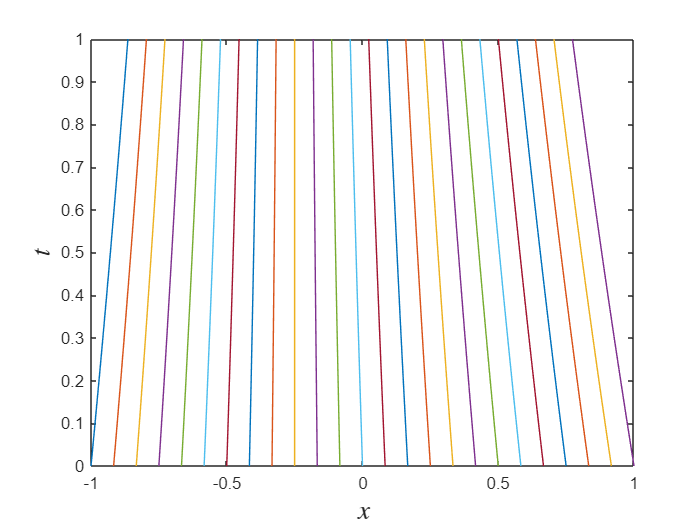

xT = zeros(size(x0));

figure(2)
for k = 1 : length(x0)
    [t_path, x_path] = ode45(u, [0, T], x0(k));
    plot(x_path, t_path);
    hold on;
    xT(k) = x_path(end);

    % Verification
%     x_path = x0(k) * exp(a*t) + b/a*(exp(a*t) - 1);
%     plot(x_path, t, '*k');
end
hold off;
xlabel('$x$', Interpreter = 'latex', FontSize = 16);
ylabel('$t$', Interpreter = 'latex', FontSize = 16);

## Conservation of mass equation

rho = zeros(1, length(x0));

for k = 1 : length(x0)
    [t_path, x_path] = ode45(u, [0 T], x0(k));

    dudx_path = dudx(t_path, x_path);
    dpath = [diff(x_path), diff(t_path)];
    h = sqrt(sum(dpath.^2, 2));

    integ = .5*(dudx_path(2:end) + dudx_path(1:end-1)).' * h;
    rho(k) = rho_0(k) * exp(-integ);
end

## Density change visualisation

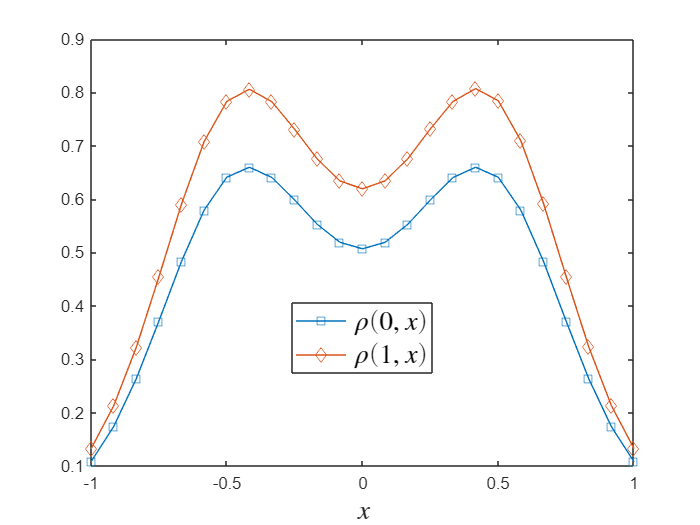

figure(3)
plot(x0, rho_0, '-s');
hold on;
plot(x0, rho, '-d');
hold off;
legend('$\rho(0, x)$', '$\rho(1, x)$', ...
    Interpreter = 'latex', FontSize = 16, Location = 'best');
xlabel('$x$', Interpreter = 'latex', FontSize = 16)